## Introduction

In this scrip, i try to test the reliability of the ramdomness of wfbm function used to generate randomness of random walk.

## Data importing

import Total Length

Length=100;

import Total_experiment_number

Total_experiment_number=10000;

import hurst parameter H

H=0.7;

## Generating

initialization

x=zeros(Total_experiment_number,Length+1);

main loop

for i=1:Total_experiment_number
    x(i,:)=wfbm(H,Length+1);
end

## Out put

averageX=zeros(Length+1,1);
RMSX=zeros(Length+1,1);
for i=1:Length+1
    averageX(i,1)=sum(x(:,i))/Total_experiment_number;
    RMSX(i,1)=sum(x(:,i).^2)/Total_experiment_number-averageX(i,1)^2;
end

plotting

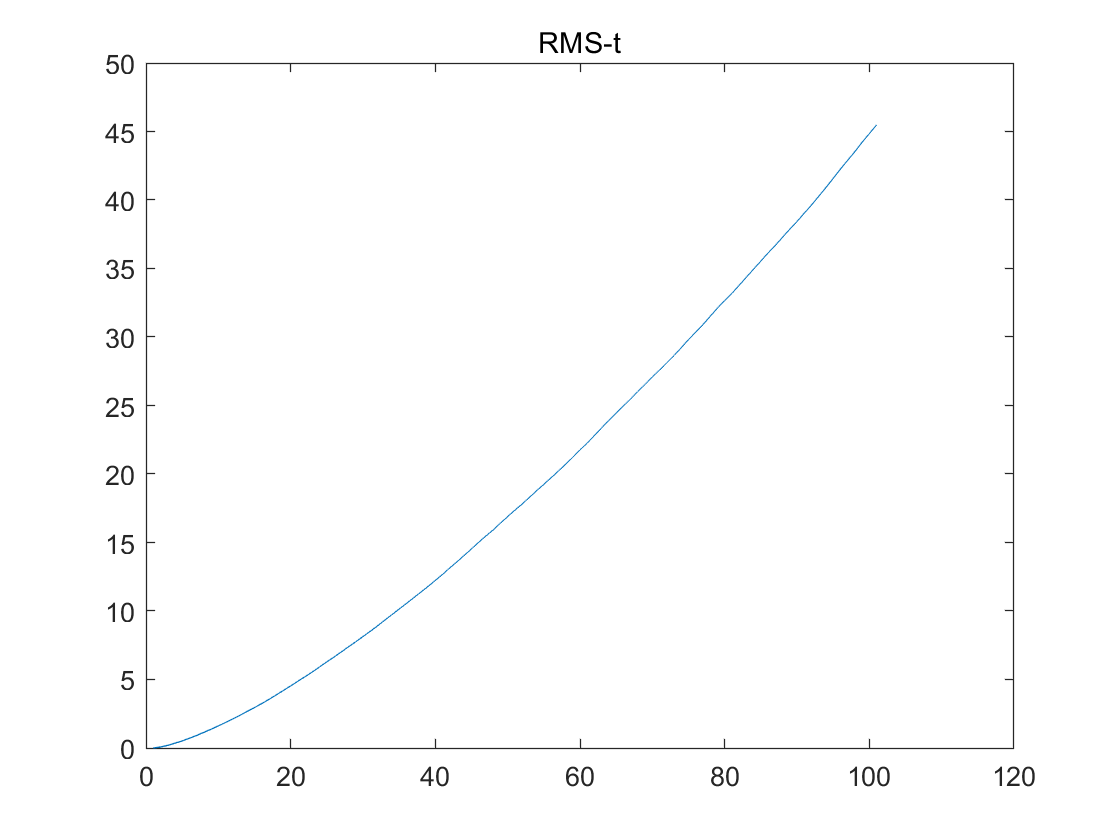

figure
plot(RMSX)
title('RMS-t')

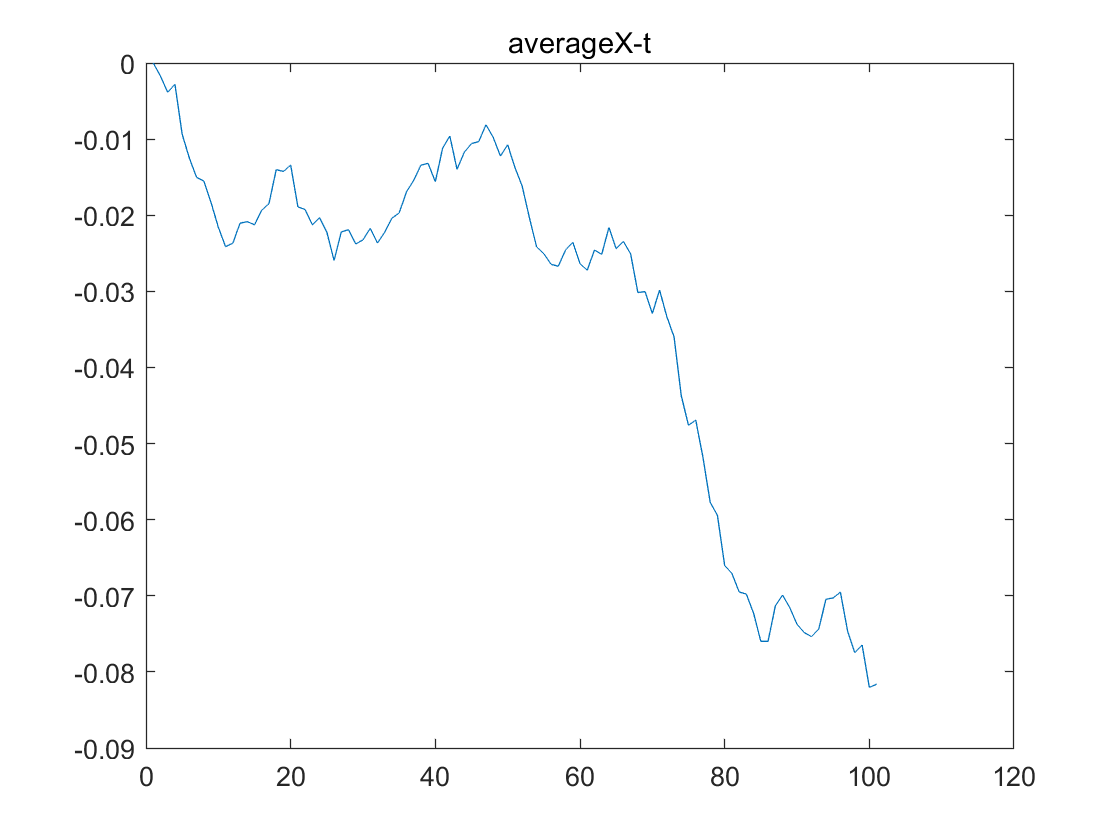


figure
plot(averageX)
title('averageX-t')

## Ending

When Total_experiment_number is 10000, the randomness is quite good.

But the average x still goes up and down, as plotted.

As Total_experiment_number goes to 100000, the average x levels off to 0.